# 3D volumetric current flow from a disc electrode: explicit solution 

## Theory

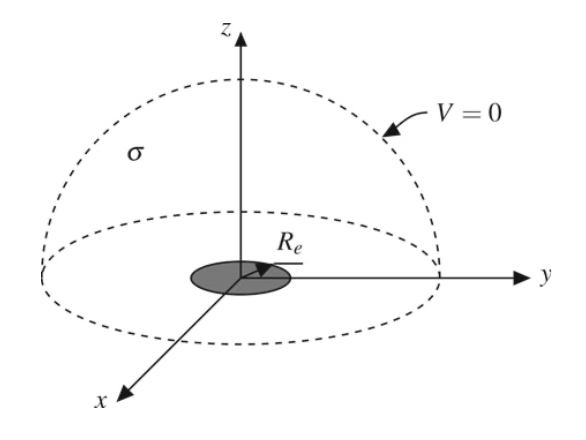

PDE: $
\nabla^2 \phi = \frac{\partial^2\phi}{\partial x^2}+ \frac{\partial^2\phi}{\partial y^2}+ \frac{\partial^2\phi}{\partial z^2}=0
$

Separation of variables: $\phi(r,z)=P(r)\,Q(z)$ 


$$r=\sqrt{ x^2+y^2}$$


Boundary conditions:

$\phi(r,z)=V_s$ if $r\le R_e$ and $z = 0
$ (on the electrode)

$J_z(r,z)=0$ $\Rightarrow$$\frac{\partial\phi}{\partial z}=0$   if $r>
 R_e$ and $z = 0
$ (xy plane outside the electrode)

clear variables;

## Symbolic evaluation of Laplacian


syms x y z r(x,y) P(r) Q(z) phi(r,z)


lpl = laplacian( P(r)*Q(z) );
lpl=collect(lpl,Q(z));
lpl = subs(lpl,r(x,y),(x^2+y^2)^0.5);
lpl = simplify(lpl,"IgnoreAnalyticConstraints",true);
syms r R_e; %this is just to simplify the notation
assume(r>0);
lpl = subs(lpl,(x^2+y^2)^0.5,r);
lpl = expand(lpl,"IgnoreAnalyticConstraints",true);
lpl=collect(lpl,Q(z)); %laplacian of phi in r,z coordinates

Laplace equation in in (r,z) coordinates: 

eq= lpl == 0 

$$eq = \left(P^{\prime \prime }\left(r\right)+\frac{P^{\prime }\left(r\right)}{r}\right)\,Q\left(z\right)+P\left(r\right)\,\frac{\partial^{2}}{\partial z^{2}}Q\left(z\right)=0$$

Divide by P(r)Q(z) and separate the r / z terms :  

eq= (1/P(r))*(     diff(P(r), r, 2) + ... 
    diff(P(r), r, 1)/r ) ... 
    == - diff(Q(z), z, 2)/Q(z) %adjusted manually, you can eventually copy/paste previous equation and perform manual operation

$$eq = \frac{\frac{\frac{\partial }{\partial r}P\left(r\right)}{r}+\frac{\partial^{2}}{\partial r^{2}}P\left(r\right)}{P\left(r\right)}=-\frac{\frac{\partial^{2}}{\partial z^{2}}Q\left(z\right)}{Q\left(z\right)}$$

## Separation of variable method

Each side of the expression is a function of r or z alone, it follows that, for both sides to to be equal, each term must be equal to a constant ($\lambda$):

syms lambda
eqr=(diff(P(r), r)/r + diff(P(r), r, 2))/P(r)==lambda

$$eqr = \frac{\frac{\frac{\partial }{\partial r}P\left(r\right)}{r}+\frac{\partial^{2}}{\partial r^{2}}P\left(r\right)}{P\left(r\right)}=\lambda$$

eqz= diff(Q(z), z, 2)/Q(z)==-lambda

$$eqz = \frac{\frac{\partial^{2}}{\partial z^{2}}Q\left(z\right)}{Q\left(z\right)}=-\lambda$$

## Equation in r: P(r)

eqr=diff(P(r), r)/r + diff(P(r), r, 2)-lambda*P(r) == 0

$$eqr = \frac{\frac{\partial }{\partial r}P\left(r\right)}{r}-\lambda \,P\left(r\right)+\frac{\partial^{2}}{\partial r^{2}}P\left(r\right)=0$$

eqr is an ordinary differential equation (ODE) and can be solved assuming that P(r) can be expressed as a power series in the form $P(r)=\sum_{k=0}^{\infty}a_k\,r^k$

syms a(k) k t P1(r) j
P1(r)=symsum(a(k)*r^k, k, 0, inf)

$$P1(r) = \sum_{k=0}^{\infty }r^{k}\,a\left(k\right)$$

We substitute the power series expression in the ODE and we manipulate the expression:

eqr=diff(P1,r,2)+diff(P1,r,1)/r-lambda*P1(r)==0 

$$eqr(r) = \left(\sum_{k=0}^{\infty }k\,r^{k-2}\,a\left(k\right)\,\left(k-1\right)\right)-\lambda \,\left(\sum_{k=0}^{\infty }r^{k}\,a\left(k\right)\right)+\frac{\sum_{k=0}^{\infty }k\,r^{k-1}\,a\left(k\right)}{r}=0$$

First term = 0 for k=0,1; Third term = 0 for k=0

eqr=(symsum(a(k)*k*(k - 1)*r^(k - 2), k, 2, sym(inf))) - ... 
    lambda*(symsum(a(k)*r^k, k, 0, sym(inf))) + ... 
     symsum(a(k)*k*r^(k - 1), k, 1, sym(inf))/r == 0

$$eqr = \left(\sum_{k=2}^{\infty }k\,r^{k-2}\,a\left(k\right)\,\left(k-1\right)\right)-\lambda \,\left(\sum_{k=0}^{\infty }r^{k}\,a\left(k\right)\right)+\frac{\sum_{k=1}^{\infty }k\,r^{k-1}\,a\left(k\right)}{r}=0$$

Include r in the third term

eqr=(symsum(a(k)*k*(k - 1)*r^(k - 2), k, 2, sym(inf))) - ... 
    lambda*(symsum(a(k)*r^k, k, 0, sym(inf))) + ... 
     symsum(a(k)*k*r^(k - 2), k, 1, sym(inf)) == 0

$$eqr = \left(\sum_{k=2}^{\infty }k\,r^{k-2}\,a\left(k\right)\,\left(k-1\right)\right)+\left(\sum_{k=1}^{\infty }k\,r^{k-2}\,a\left(k\right)\right)-\lambda \,\left(\sum_{k=0}^{\infty }r^{k}\,a\left(k\right)\right)=0$$

The central term for k=1 is equal to $a_1/r$

eqr=(symsum(a(k)*k*(k - 1)*r^(k - 2), k, 2, sym(inf))) - ... 
    lambda*(symsum(a(k)*r^k, k, 0, sym(inf))) + ... 
    (a(1)/r+symsum(a(k)*k*r^(k - 2), k, 2, sym(inf))) == 0

$$eqr = \left(\sum_{k=2}^{\infty }k\,r^{k-2}\,a\left(k\right)\,\left(k-1\right)\right)+\left(\sum_{k=2}^{\infty }k\,r^{k-2}\,a\left(k\right)\right)-\lambda \,\left(\sum_{k=0}^{\infty }r^{k}\,a\left(k\right)\right)+\frac{a\left(1\right)}{r}=0$$

Collect the summations with the same indexes

eqr=(symsum(r^(k - 2)*(a(k)*k*(k - 1)+a(k)*k), k, 2, sym(inf))) - ... 
    lambda*(symsum(a(k)*r^k, k, 0, sym(inf))) + a(1)/r == 0;
eqr=simplify(eqr,"IgnoreAnalyticConstraints",true)

$$eqr = \frac{a\left(1\right)}{r}-\lambda \,\left(\sum_{k=0}^{\infty }r^{k}\,a\left(k\right)\right)+\left(\sum_{k=2}^{\infty }k^{2}\,r^{k-2}\,a\left(k\right)\right)=0$$

In the third summation we make the substitution j=k-2 (k=j+2)

eqr=(symsum((j+2)^2*r^(j)*a(j+2), j, 0, sym(inf))) ... %copy/paste and manual substitution
     - lambda*(symsum(r^k*a(k), k, 0, sym(inf))) + a(1)/r == 0 

$$eqr = \frac{a\left(1\right)}{r}-\lambda \,\left(\sum_{k=0}^{\infty }r^{k}\,a\left(k\right)\right)+\left(\sum_{j=0}^{\infty }r^{j}\,a\left(j+2\right)\,{\left(j+2\right)}^{2}\right)=0$$

j is a dummy index, we can use again k

eqr=a(1)/r + (symsum(r^k* (a(k + 2)*(k + 2)^2-lambda*a(k)), k, 0, sym(inf))) == 0 

$$eqr = \frac{a\left(1\right)}{r}-\left(\sum_{k=0}^{\infty }r^{k}\,\left(\lambda \,a\left(k\right)-a\left(k+2\right)\,{\left(k+2\right)}^{2}\right)\right)=0$$

Since eqr has to be 0 for all r, then all the coefficients of the power of r must be 0 


$$a_1=0$$



$$a_{k+2}=\frac{\lambda\,a_k}{(k+2)^2}=M_k\,a_k
$$


k odd (1, 3, 5, 7....) -> $a_k=0
$ 


$$a_{3}=M_k\,a_1=0 \,\,\,\,\,
a_5=M_k\,a_3=0 \,\,\,\,\,
a_7=M_k\,a_5=0 \,\,\,\,\, ....$$


k even (0, 2, 4, 6 ...) 

 
$$k=0 \,\,\,\,\,\, a_2= \frac{\lambda}{2^2}\,a_0 \\
k=2 \,\,\,\,\,\, a_4= \frac{\lambda}{4^2}\,a_2= \frac{\lambda}{4^2}\,\frac{\lambda}{2^2}\,a_0 = \frac{\lambda^2}{4^2\,2^2}\,a_0\\
k=4 \,\,\,\,\,\, a_6= \frac{\lambda}{6^2}\,a_4= \frac{\lambda}{6^2}\,\frac{\lambda}{4^2}\,\frac{\lambda}{2^2}\,a_0 = \frac{\lambda^3}{6^2\,4^2\,2^2}\,a_0\\

a_k=\frac{\lambda^{k/2}}{k^2\,(k-2)^2\, (k-4)^2\,... \, 2^2}\,a_0\\$$


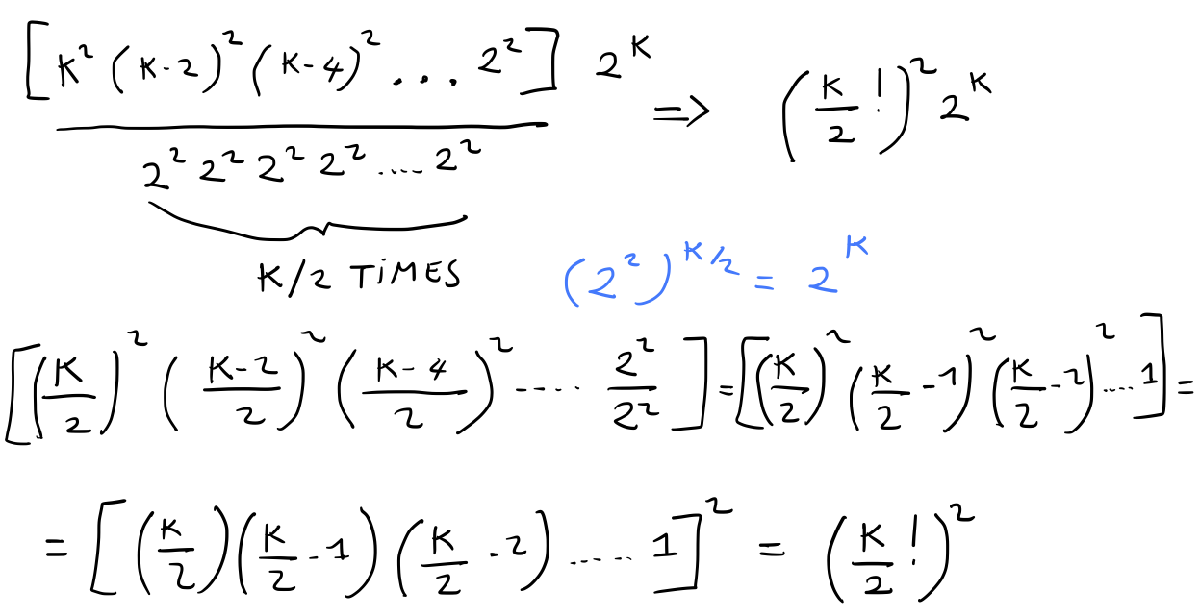


$$a_k=\frac{\lambda^{k/2}}{\left(\frac{k}{2}! \right)^2\,2^k}\,a_0$$


We obtain (n=k/2):


$$P(r)=a_0 \, \sum_{n=0}^{\infty}  \left[     \frac{\lambda^{n} \, r^{2n}} {\left(n! \right)^2\,2^{2n}} \right]$$


$\lambda$ and $a_0
$ must be real to have real valued P(r). $\phi$ will approach to ground for $r \to \infty$, this can only happen if  coefficient of $r^{2n}$ alternate in signs  which implies $\lambda < 0$, considering  $\lambda=-\mu^2$ with $\mu>0$we have:


$$P(r)=a_0 \, \sum_{n=0}^{\infty}  \left[     (-1)^n\,\frac{\mu^{2n} \, r^{2n}} {\left(n! \right)^2\,2^{2n}} \right]=a_0 \, \sum_{n=0}^{\infty}  \left[     (-1)^n\,\frac{{(\mu r)}^{2n} } {\left(n! \right)^2\,2^{2n}} \right]$$


Recall the  Bessel function of first kind of order zero: 


$$J_0(x)=1- {x^2 \over 2^2} + {x^4 \over {2^2 \, 4^2} }- {x^6 \over {2^2 \, 4^2 \, 6^2} } + ...$$



$$P(r)=a_0 \, J_0( \mu \, r)$$


syms a_0
mu= sym('mu', 'positive');
P(r)=a_0*besselj(0,mu*r)

$$P(r) = a_{0}\,J_{0}\left(\mu \,r\right)$$

## Equation in z: Q(z)

syms C_2 K


Recall: $\lambda$ is negative! 


lambda=-mu^2 

$$lambda = -\mu^{2}$$


eqz

$$eqz = \frac{\frac{\partial^{2}}{\partial z^{2}}Q\left(z\right)}{Q\left(z\right)}=-\lambda$$

Manipulate the equation:

eqz=diff(Q(z), z, 2) + lambda*Q(z)==0

$$eqz = \frac{\partial^{2}}{\partial z^{2}}Q\left(z\right)-\mu^{2}\,Q\left(z\right)=0$$

This can be solved using dsolve (note characteristic equation has real roots $\pm \mu$): 

Q(z) = dsolve(eqz)

$$Q(z) = C_{1}\,{\mathrm{e}}^{\mu \,z}+C_{2}\,{\mathrm{e}}^{-\mu \,z}$$

V will approach to 0 for $z \to \infty $ then $c_1=0$ and 

Q(z)= C_2*exp((-mu*z))

$$Q(z) = C_{2}\,{\mathrm{e}}^{-\mu \,z}$$

with $\mu>0$

## PDE solution

We then obtain the PDE solution $\phi(r,z)=P(r)\,Q(z)$

phi(r,z)=P(r)*Q(z)

$$phi(r, z) = C_{2}\,a_{0}\,{\mathrm{e}}^{-\mu \,z}\,J_{0}\left(\mu \,r\right)$$

phi(r,z)=K*besselj(0,mu*r)*exp(-mu*z)

$$phi(r, z) = K\,{\mathrm{e}}^{-\mu \,z}\,J_{0}\left(\mu \,r\right)$$

where $K=C_2\,a_0$ is a new constant (note: If $\mu$ changes, a different K determines the solution, thus: K=K($\mu$))

The general solution of the PDE can be obtained by summing all possible solutions (linearity) of the above reported form (note that for each value of the constant $\mu$ we have a different value of the constant K to form a solution). The solution can be obtained by representing the sum using a definite integral in u: 

$\phi(r, z)=\int_0^\infty K(\mu)\,J_0(\mu r)e^{-\mu z}\,d \mu$  (sol)

To determine $K(\mu)
$ we implement the following mixed boundary conditions valid for z=0: 

$\phi=V_s$ if $r \leq R_e$ (prescribed potential)

$\frac{\partial \phi}{\partial z}=0$ if $r > R_e$ (xy plane is electrically insulating, so the component of the current density perpendicular to the plane is 0)

Where Re is the electrode radius

Then we obtain: 

$V_s=\int_0^\infty K(\mu)\,J_0(\mu r)\,d \mu$ for z=0 and $r \leq R_e$            (b1)

$0=\int_0^\infty -\mu K(\mu)\,J_0(\mu r)\,d \mu$ for z=0 and $r > R_e$         (b2)

We substitute $\rho={r \over R_e}$

$V_s=\int_0^\infty K(\mu)\,J_0(\mu \rho R_e)\,d \mu$ for z=0 and $0 \leq \rho \leq 1$

$0=\int_0^\infty -\mu K(\mu)\,J_0(\mu \rho R_e)\,d \mu$ for z=0 and $\rho > 1$

syms K(mu) epsilon psi(epsilon) rho R_e
assume(R_e>0);


To solve the above integral equations for $K(\mu)$ we set 

K(mu)=int(psi(epsilon)*cos(mu*R_e*epsilon),epsilon,0,1)

$$K(mu) = \int_{0}^{1}\psi \left(\epsilon \right)\,\cos\left(R_{e}\,\epsilon \,\mu \right)\mathrm{d}\epsilon$$

We then use the integral form of K in the left term of (b2) 

b2=int(mu*K(mu)*besselj(0,mu*R_e*rho),mu,0,inf)

$$b2 = \int_{0}^{\infty }\mu \,\int_{0}^{1}\psi \left(\epsilon \right)\,\cos\left(R_{e}\,\epsilon \,\mu \right)\mathrm{d}\epsilon \,J_{0}\left(R_{e}\,\mu \,\rho \right)\mathrm{d}\mu$$

We integrate by parts: 

K(mu)=integrateByParts(K(mu),cos(mu*R_e*epsilon))

$$K(mu) = \frac{\psi \left(1\right)\,\sin\left(R_{e}\,\mu \right)}{R_{e}\,\mu }-\int_{0}^{1}\frac{\sin\left(R_{e}\,\epsilon \,\mu \right)\,\frac{\partial }{\partial \epsilon }\psi \left(\epsilon \right)}{R_{e}\,\mu }\mathrm{d}\epsilon$$


b2=expand(int(mu*K(mu)*besselj(0,mu*R_e*rho),mu,0,inf))

$$b2 = \int_{0}^{\infty }\frac{\psi \left(1\right)\,\sin\left(R_{e}\,\mu \right)\,J_{0}\left(R_{e}\,\mu \,\rho \right)}{R_{e}}\mathrm{d}\mu +\int_{0}^{\infty }\left(-\frac{\int_{0}^{1}\sin\left(R_{e}\,\epsilon \,\mu \right)\,\frac{\partial }{\partial \epsilon }\psi \left(\epsilon \right)\mathrm{d}\epsilon \,J_{0}\left(R_{e}\,\mu \,\rho \right)}{R_{e}}\right)\mathrm{d}\mu$$

first term of b2:

b2_1= int((psi(sym(1))*sin(R_e*mu)*besselj(0,mu*R_e*rho)),mu,0,inf)/R_e

$$b2\_1 = \frac{\int_{0}^{\infty }\psi \left(1\right)\,\sin\left(R_{e}\,\mu \right)\,J_{0}\left(R_{e}\,\mu \,\rho \right)\mathrm{d}\mu }{R_{e}}$$

second term of b2:

b2_2=-int( int(sin(R_e*epsilon*mu)*diff(psi(epsilon), epsilon), epsilon, 0, 1) ... 
    *besselj(0, R_e*mu*rho), mu, 0, inf)/R_e

$$b2\_2 = -\frac{\int_{0}^{\infty }\int_{0}^{1}\sin\left(R_{e}\,\epsilon \,\mu \right)\,\frac{\partial }{\partial \epsilon }\psi \left(\epsilon \right)\mathrm{d}\epsilon \,J_{0}\left(R_{e}\,\mu \,\rho \right)\mathrm{d}\mu }{R_{e}}$$

second term of b2 inverting the integrals: 

b2_2=-int(diff(psi(epsilon), epsilon)* ... 
    (int( sin(R_e*epsilon*mu)*besselj(0, R_e*mu*rho),mu,0,inf)),epsilon,0,1)/R_e

$$b2\_2 = -\frac{\int_{0}^{1}\int_{0}^{\infty }\sin\left(R_{e}\,\epsilon \,\mu \right)\,J_{0}\left(R_{e}\,\mu \,\rho \right)\mathrm{d}\mu \,\frac{\partial }{\partial \epsilon }\psi \left(\epsilon \right)\mathrm{d}\epsilon }{R_{e}}$$


b2=b2_1+b2_2

$$b2 = \frac{\int_{0}^{\infty }\psi \left(1\right)\,\sin\left(R_{e}\,\mu \right)\,J_{0}\left(R_{e}\,\mu \,\rho \right)\mathrm{d}\mu }{R_{e}}-\frac{\int_{0}^{1}\int_{0}^{\infty }\sin\left(R_{e}\,\epsilon \,\mu \right)\,J_{0}\left(R_{e}\,\mu \,\rho \right)\mathrm{d}\mu \,\frac{\partial }{\partial \epsilon }\psi \left(\epsilon \right)\mathrm{d}\epsilon }{R_{e}}$$

Weber's discontinuous integral identities

$\int_0^\infty J_0(a \,x)\,sin(bx)\,dx =   
 \begin{cases} \frac{1}{\sqrt {b^2-a^2}}, & (a<b)   \\ 
0 , & (a>b) \end{cases}$     (id1)

$\int_0^\infty J_0(a \,x)\,cos(bx)\,dx =   
 \begin{cases} 0 , & (a<b) \\ \frac{1}{\sqrt {a^2-b^2}}, & (a>b)   
 \end{cases}$     (id2)

The first term (b2_1) is 0 (see id1 -> $a=\rho R_e$ and $b=R_e$ with $\rho>1$we have a>b

For the second term considering 

int(sin(R_e*epsilon*mu)*besselj(0, (R_e*mu*rho)), mu, 0, inf)

$$ans = \int_{0}^{\infty }\sin\left(R_{e}\,\epsilon \,\mu \right)\,J_{0}\left(R_{e}\,\mu \,\rho \right)\mathrm{d}\mu$$

we consider again id1 with $a=\rho R_e$ and $b=R_e \epsilon$ -> a>b since $\rho>1$ and $0 \leq \epsilon \leq 1 $, thus the second term of the integral b2_2=o and **thus the boundary condition b_2 is verified.**

We now substitute 

K(mu)=int(psi(epsilon)*cos(mu*R_e*epsilon),epsilon,0,1) %defined before the integration per parts

$$K(mu) = \int_{0}^{1}\psi \left(\epsilon \right)\,\cos\left(R_{e}\,\epsilon \,\mu \right)\mathrm{d}\epsilon$$

in the first boundary condition (b1) ($V_s=\int_0^\infty K(\mu)\,J_0(\mu \rho R_e)\,d \mu$ for z=0 and $0 \leq \rho \leq 1$)



b1=int(K(mu)*besselj(0,mu*rho*R_e),mu,0,inf)

$$b1 = \int_{0}^{\infty }\int_{0}^{1}\psi \left(\epsilon \right)\,\cos\left(R_{e}\,\epsilon \,\mu \right)\mathrm{d}\epsilon \,J_{0}\left(R_{e}\,\mu \,\rho \right)\mathrm{d}\mu$$

changing the integration order we obtain 

b1=int( psi(epsilon)* int(besselj(0,mu*rho*R_e)*cos(R_e*epsilon*mu),mu,0,inf),epsilon,0,1)

$$b1 = \int_{0}^{1}\psi \left(\epsilon \right)\,\int_{0}^{\infty }\cos\left(R_{e}\,\epsilon \,\mu \right)\,J_{0}\left(R_{e}\,\mu \,\rho \right)\mathrm{d}\mu \mathrm{d}\epsilon$$

using the second Weber's integral identity (id2) with $0 \leq \rho \leq 1$can be written as 

b1=(1/R_e)*int( psi(epsilon)* 1/((rho)^2-(epsilon)^2)^0.5,epsilon,0,rho)

$$b1 = \frac{\int_{0}^{\rho }\frac{\psi \left(\epsilon \right)}{\sqrt{\rho^{2}-\epsilon^{2}}}\mathrm{d}\epsilon }{R_{e}}$$

So $\psi{(\epsilon)} $ satisfies the following integral equation:

syms V_s 
(1/R_e)*int( psi(epsilon)* 1/((rho)^2-(epsilon)^2)^0.5,epsilon,0,rho)==V_s

$$ans = \frac{\int_{0}^{\rho }\frac{\psi \left(\epsilon \right)}{\sqrt{\rho^{2}-\epsilon^{2}}}\mathrm{d}\epsilon }{R_{e}}=V_{s}$$

with $0 \leq \rho \leq 1$.

Using the identity 


$$\int_0^\rho \frac{d \epsilon}{\sqrt{\rho^2-\epsilon^2}} =\left[ sin^{-1}\left( \frac{\epsilon}{\rho}  \right) \right]_0^\rho=\frac{\pi}{2}$$


Then we use the value of : 


$$\psi(\epsilon)=\frac{2\,V_s\,R_e}{\pi}$$


to  obtain $K(\mu)
$ we compute

K(mu)=int(((2*V_s*R_e)/pi)*cos(mu*R_e*epsilon),epsilon,0,1)

$$K(mu) = \frac{2\,V_{s}\,\sin\left(R_{e}\,\mu \right)}{\mu \,\pi }$$

We then include K in the PDE general solution $\phi(r, z)=\int_0^\infty K(\mu)\,J_0(\mu r)e^{-\mu z}\,d \mu$ : 

phi(r,z)=int(K(mu)*besselj(0,mu*r)*exp(-mu*z),mu,0,inf)

$$phi(r, z) = \int_{0}^{\infty }\frac{2\,V_{s}\,{\mathrm{e}}^{-\mu \,z}\,\sin\left(R_{e}\,\mu \right)\,J_{0}\left(\mu \,r\right)}{\mu \,\pi }\mathrm{d}\mu$$

Using the following identity: 


$$\int_0^\infty{ \frac{J_0(ax)\,sin(bx)}{x}\,e^{-cx}dx}=tan^{-1}\left( \frac{b}{\gamma}\right) \\

\gamma=\sqrt{ \frac{a^2+c^2-b^2+\sqrt{(a^2+c^2-b^2)^2+4b^2c^2}}{2}     }$$


we finally obtain ($a=r$, $b=R_e$, $c=z$) the voltage in the hemispherical region


$$\phi(r,z)=\frac{2 V_s}{\pi} \, tan^{-1}\left( \frac{R_e \, \sqrt{2}}{\sqrt{ r^2+z^2-{R_e}^2+\sqrt{(r^2+z^2-{R_e}^2)^2+4{R_e}^2z^2}     }}\right) \\
$$


phi(r,z)=(2*V_s/pi)*atan((R_e*2^0.5)/(r^2+z^2-R_e^2+((r^2+z^2-R_e^2)^2+4*z^2*R_e^2)^0.5)^0.5)

$$phi(r, z) = \frac{2\,V_{s}\,\mathrm{atan}\left(\frac{\sqrt{2}\,R_{e}}{\sqrt{\sqrt{{\left(-{R_{e}}^{2}+r^{2}+z^{2}\right)}^{2}+4\,{R_{e}}^{2}\,z^{2}}-{R_{e}}^{2}+r^{2}+z^{2}}}\right)}{\pi }$$

We evaluate the potential for z=0:

phi_z0=subs(phi,z,0)

$$phi\_z0(r, z) = \frac{2\,V_{s}\,\mathrm{atan}\left(\frac{\sqrt{2}\,R_{e}}{\sqrt{\sqrt{{\left({R_{e}}^{2}-r^{2}\right)}^{2}}-{R_{e}}^{2}+r^{2}}}\right)}{\pi }$$

If $r < R_e$ (i.e. on the electrode) the denominator of the arctan is zero, then the solution is: 


$$\phi(r,0)_{disc}=\frac{2 V_s}{\pi}\,\frac{\pi}{2}=V_s$$


as required by the boundary conditions. 

## Electrode current density, total current and access resistance

The current density is given by:


$$\mathbf{J}=-\sigma \nabla \phi=-\sigma
         \left[\begin{array}{@{}c@{}}
    \frac{\partial \phi}{\partial x} \\
     \frac{\partial \phi}{\partial y} \\
 \frac{\partial \phi}{\partial z} \\
    \end{array} \right]
     $$


On the disc electrode, only the z-component is non zero because it is isopotential ($\phi_{disc}=V_s=1V$):

$J_z=-\sigma\frac{\partial \phi}{\partial z}$ on the disc: $z=0$ $r<R_e$

dphiz=simplify(diff(phi,z))

$$dphiz(r, z) = -\frac{2\,\sqrt{2}\,R_{e}\,V_{s}\,z}{\pi \,\sqrt{{\left(-{R_{e}}^{2}+r^{2}+z^{2}\right)}^{2}+4\,{R_{e}}^{2}\,z^{2}}\,\sqrt{\sqrt{{\left(-{R_{e}}^{2}+r^{2}+z^{2}\right)}^{2}+4\,{R_{e}}^{2}\,z^{2}}-{R_{e}}^{2}+r^{2}+z^{2}}}$$

Note the limit of Jz for z=0 on the electrode (r<Re) is undetermined: 


assume(r<R_e)
[num den]=numden(dphiz)

$$num(r, z) = -2\,\sqrt{2}\,R_{e}\,V_{s}\,z$$

$$den(r, z) = \begin{array}{l} \pi \,\sqrt{r^{2}-{R_{e}}^{2}+z^{2}+\sigma_{1}}\,\sigma_{1}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{R_{e}}^{4}-2\,{R_{e}}^{2}\,r^{2}+2\,{R_{e}}^{2}\,z^{2}+r^{4}+2\,r^{2}\,z^{2}+z^{4}} \end{array}$$

limit(num,z,0,'right')

$$ans(r) = 0$$

den_ondisc=simplify(limit(den,z,0,'righ'))

$$den\_ondisc(r) = \pi \,\left|{R_{e}}^{2}-r^{2}\right|\,\sqrt{\left|{R_{e}}^{2}-r^{2}\right|-{R_{e}}^{2}+r^{2}}$$

Note the above expression is always zero, example:

subs(den_ondisc,r,R_e/2)

$$ans(r) = 0$$

The limit of Jz for z=0 out of the electrode (r>Re) is zero as expected by the boundary conditions: 


assume(r>R_e)
[num den]=numden(dphiz)

$$num(r, z) = -2\,\sqrt{2}\,R_{e}\,V_{s}\,z$$

$$den(r, z) = \begin{array}{l} \pi \,\sqrt{r^{2}-{R_{e}}^{2}+z^{2}+\sigma_{1}}\,\sigma_{1}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{R_{e}}^{4}-2\,{R_{e}}^{2}\,r^{2}+2\,{R_{e}}^{2}\,z^{2}+r^{4}+2\,r^{2}\,z^{2}+z^{4}} \end{array}$$

limit(num,z,0)

$$ans(r) = 0$$

den_outdisc=simplify(limit(den,z,0))

$$den\_outdisc(r) = \pi \,\left|{R_{e}}^{2}-r^{2}\right|\,\sqrt{\left|{R_{e}}^{2}-r^{2}\right|-{R_{e}}^{2}+r^{2}}$$

Note the above expression is always non zero, example:

subs(den_outdisc,r,2*R_e)

$$ans(r) = 3\,\pi \,{R_{e}}^{2}\,\sqrt{6\,{R_{e}}^{2}}$$

syms beta(r,z) R_e sigma%I define again to reset the previous assumptions
assume(R_e>0)
dphiz=simplify(diff(phi,z))

$$dphiz(r, z) = -\frac{2\,\sqrt{2}\,R_{e}\,V_{s}\,z}{\pi \,\sqrt{{\left(-{R_{e}}^{2}+r^{2}+z^{2}\right)}^{2}+4\,{R_{e}}^{2}\,z^{2}}\,\sqrt{\sqrt{{\left(-{R_{e}}^{2}+r^{2}+z^{2}\right)}^{2}+4\,{R_{e}}^{2}\,z^{2}}-{R_{e}}^{2}+r^{2}+z^{2}}}$$

betaval=- R_e^2 + r^2 + z^2

$$betaval = -{R_{e}}^{2}+r^{2}+z^{2}$$

dphiz=subs(dphiz,betaval,beta)

$$dphiz(r, z) = -\frac{2\,\sqrt{2}\,R_{e}\,V_{s}\,z}{\pi \,\sqrt{\beta \left(r,z\right)+\sqrt{4\,{R_{e}}^{2}\,z^{2}+{\beta \left(r,z\right)}^{2}}}\,\sqrt{4\,{R_{e}}^{2}\,z^{2}+{\beta \left(r,z\right)}^{2}}}$$

alpha=(4*R_e^2*z^2 + beta^2)^0.5

$$alpha(r, z) = \sqrt{4\,{R_{e}}^{2}\,z^{2}+{\beta \left(r,z\right)}^{2}}$$


alpha=subs(alpha,beta,betaval)

$$alpha(r, z) = \sqrt{{\left(-{R_{e}}^{2}+r^{2}+z^{2}\right)}^{2}+4\,{R_{e}}^{2}\,z^{2}}$$

We approximate alpha with its Taylor approximation about z=0: 


alpha_a=taylor(alpha,z,0,'Order',3)

$$alpha\_a(r, z) = \sqrt{{\left({R_{e}}^{2}-r^{2}\right)}^{2}}+\frac{z^{2}\,\left({R_{e}}^{2}+r^{2}\right)}{\sqrt{{\left({R_{e}}^{2}-r^{2}\right)}^{2}}}$$


dphiz=subs(dphiz,beta,betaval)

$$dphiz(r, z) = -\frac{2\,\sqrt{2}\,R_{e}\,V_{s}\,z}{\pi \,\sqrt{{\left(-{R_{e}}^{2}+r^{2}+z^{2}\right)}^{2}+4\,{R_{e}}^{2}\,z^{2}}\,\sqrt{\sqrt{{\left(-{R_{e}}^{2}+r^{2}+z^{2}\right)}^{2}+4\,{R_{e}}^{2}\,z^{2}}-{R_{e}}^{2}+r^{2}+z^{2}}}$$


dphiz_a = simplify( subs(dphiz,alpha,alpha_a))

$$dphiz\_a(r, z) = \begin{array}{l} -\frac{2\,\sqrt{2}\,R_{e}\,V_{s}\,z\,\sigma_{1}}{\pi \,\sqrt{\sigma_{1}-{R_{e}}^{2}+r^{2}+z^{2}+\frac{z^{2}\,\left({R_{e}}^{2}+r^{2}\right)}{\sigma_{1}}}\,\left({R_{e}}^{4}-2\,{R_{e}}^{2}\,r^{2}+{R_{e}}^{2}\,z^{2}+r^{4}+r^{2}\,z^{2}\right)}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{\left({R_{e}}^{2}-r^{2}\right)}^{2}} \end{array}$$

num=-2*sqrt(sym(2))*R_e*V_s*z*sqrt((R_e^2 - r^2)^2)%directly selected from dphiz_a

$$num = -2\,\sqrt{2}\,R_{e}\,V_{s}\,z\,\sqrt{{\left({R_{e}}^{2}-r^{2}\right)}^{2}}$$


den=sym(pi)*sqrt(sqrt((R_e^2 - r^2)^2) - R_e^2 + r^2 + z^2 + ... 
    (z^2*(R_e^2 + r^2))/sqrt((R_e^2 - r^2)^2))*(R_e^4 - 2*R_e^2*r^2 + R_e^2*z^2 + r^4 + r^2*z^2) ...
    %directly selected from dphiz_a

$$den = \pi \,\sqrt{\sqrt{{\left({R_{e}}^{2}-r^{2}\right)}^{2}}-{R_{e}}^{2}+r^{2}+z^{2}+\frac{z^{2}\,\left({R_{e}}^{2}+r^{2}\right)}{\sqrt{{\left({R_{e}}^{2}-r^{2}\right)}^{2}}}}\,\left({R_{e}}^{4}-2\,{R_{e}}^{2}\,r^{2}+{R_{e}}^{2}\,z^{2}+r^{4}+r^{2}\,z^{2}\right)$$

Arrange manually the denominator  of dphiz_a

den=pi*((abs(R_e^2-r^2) -(R_e^2-r^2)+z^2+ (z^2*(R_e^2+r^2))/(abs(R_e^2-r^2) )  )^0.5)... 
    *((R_e^2-r^2)^2+z^2*(R_e^2+r^2))

$$den = \pi \,\left(z^{2}\,\left({R_{e}}^{2}+r^{2}\right)+{\left({R_{e}}^{2}-r^{2}\right)}^{2}\right)\,\sqrt{\left|{R_{e}}^{2}-r^{2}\right|-{R_{e}}^{2}+r^{2}+z^{2}+\frac{z^{2}\,\left({R_{e}}^{2}+r^{2}\right)}{\left|{R_{e}}^{2}-r^{2}\right|}}$$

If r<$R_e$ we can write the denominator as: 

den=sym(pi)*(z^2*(R_e^2 + r^2) + (R_e^2 - r^2)^2)*z* ... 
    sqrt(1 + ((R_e^2 + r^2))/abs((R_e^2 - r^2)))

$$den = \pi \,z\,\left(z^{2}\,\left({R_{e}}^{2}+r^{2}\right)+{\left({R_{e}}^{2}-r^{2}\right)}^{2}\right)\,\sqrt{\frac{{R_{e}}^{2}+r^{2}}{\left|{R_{e}}^{2}-r^{2}\right|}+1}$$

note that in this condition the denominator is multiple of z, then we have a non zero Jz (in case r>Re, outside th electrode, the denominator is not multiple of z, then the dphiz is zero and thus Jz=0 outside the electrode as imposed by the boundary conditions).

dphiz_a=num/den

$$dphiz\_a = -\frac{2\,\sqrt{2}\,R_{e}\,V_{s}\,\sqrt{{\left({R_{e}}^{2}-r^{2}\right)}^{2}}}{\pi \,\left(z^{2}\,\left({R_{e}}^{2}+r^{2}\right)+{\left({R_{e}}^{2}-r^{2}\right)}^{2}\right)\,\sqrt{\frac{{R_{e}}^{2}+r^{2}}{\left|{R_{e}}^{2}-r^{2}\right|}+1}}$$

Jz=-sigma*subs(dphiz_a,z,0)

$$Jz = \frac{2\,\sqrt{2}\,R_{e}\,V_{s}\,\sigma \,\sqrt{{\left({R_{e}}^{2}-r^{2}\right)}^{2}}}{\pi \,{\left({R_{e}}^{2}-r^{2}\right)}^{2}\,\sqrt{\frac{{R_{e}}^{2}+r^{2}}{\left|{R_{e}}^{2}-r^{2}\right|}+1}}$$

Rearranging we obtain the expression of the current density on the electrode (r<$R_e$): 


$$J_z=\frac{2 \sigma V_s } {\pi \sqrt{{R_e}^2-r^2}}$$



Jz=(2*sigma*V_s)/(pi*(R_e^2-r^2)^0.5)

$$Jz = \frac{2\,V_{s}\,\sigma }{\pi \,\sqrt{{R_{e}}^{2}-r^{2}}}$$


$$I_s=\int_0^{R_e}J_z 2\pi r dr$$


I_s=int(Jz*2*pi*r,r,0,R_e)

$$I\_s = 4\,R_{e}\,V_{s}\,\sigma$$

R_s=V_s/I_s

$$R\_s = \frac{1}{4\,R_{e}\,\sigma }$$

Using the problem data: $R_e=5$mm, $V_s=1$ V, $\sigma =1
$ S/m

R_e=5e-3; V_s=1; sigma=1;
I_s=eval(I_s)

I_s = 0.0200

R_s=eval(R_s)

R_s = 50

phi=eval(phi)

$$phi = \frac{2\,\mathrm{atan}\left(\frac{\sqrt{2}}{200\,\sqrt{\sqrt{{\left(r^{2}+z^{2}-\frac{1}{40000}\right)}^{2}+\frac{z^{2}}{10000}}+r^{2}+z^{2}-\frac{1}{40000}}}\right)}{\pi }$$

## Plot the voltage distribution

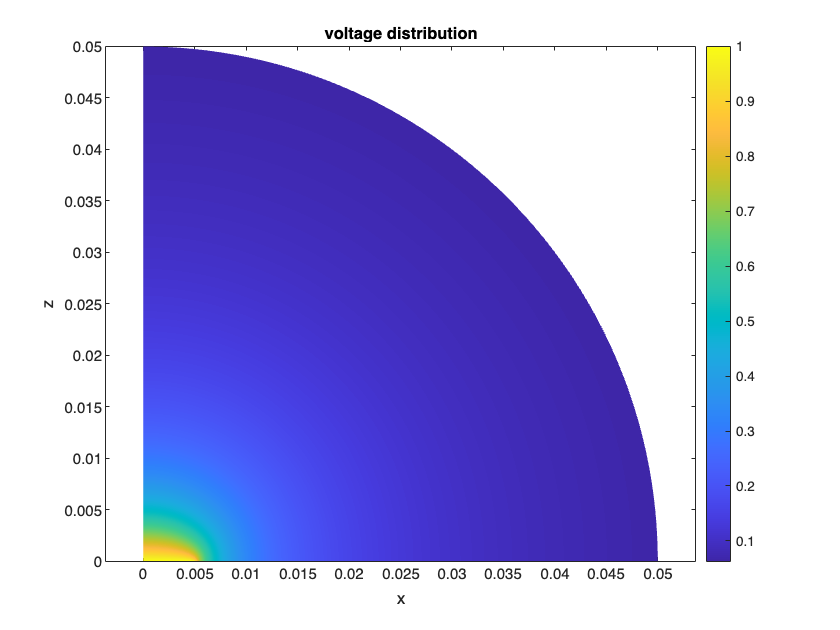


Ld=50e-3;
n=100; %N=101 number of r elements
m=100; %M=101 number of theta elements
d=0:Ld/n:Ld;
th=0:(pi/2)/m:pi/2;


for i=1:length(d)
    for j=1:length(th)
        r=d(i)*cos(th(j));
        z=d(i)*sin(th(j));
        PHI(j,i)=eval(phi); %electric potential on the grid 
    end 
end

[D,TH]=meshgrid(d,th);
%Matlab help: Cartesian rectangular grid in 2-D or 3-D 
% [X,Y] = meshgrid(x,y) returns 2-D grid coordinates based on the
% coordinates contained in vectors x and y. 
% X is a matrix where each row is a copy of x, and Y is a matrix 
% where each column is a copy of y. 
% The grid represented by the coordinates X and Y has length(y) 
% rows and length(x) columns.
X=D.*cos(TH);
Z=D.*sin(TH);


pcolor(X,Z,PHI); colorbar; axis('equal'); shading('interp'); 
title('voltage distribution');
xlabel('x'); ylabel('z');

### How to plot 2d-distributions